[cities, best_tour] = read_tsp();
D = pdist(cities);
Z = squareform(D);
best_length = tour_length(Z, best_tour);

strategy = input("Please input the local search strategy (1 for inversion, " + ...
    "2 for insertion, 3 for displacement, 4 for swap:")

strategy =      3


switch strategy
    case 1
        f = @inversion_mutation;
    case 2
        f = @insertion_mutation;
    case 3
        f = @displacement_mutation;
    case 4
        f = @swap_mutation;
    otherwise
        disp("Invalid input, exit");
        exit;
end

tour = randperm(100)';

T = 5000;
T_end = 0.01;
q = 0.98;
L = 1000;

iteration = 0;
while T > T_end && tour_length(Z, tour) >= 20751*1.1
    %fprintf("T = %f\n", T);
    for i = 1:L
        new_tour = f(tour);
        difference = tour_length(Z, new_tour) - tour_length(Z, tour);
        if difference <= 0 || rand() <= exp(-difference/T)
            tour = new_tour;  
        end
    end    
    T = T*q;  
    iteration = iteration + 1;
end

fprintf("total iteration: %d\n", iteration);

total iteration: 359


tour_length(Z, tour)

ans =      2.256385517837002e+04


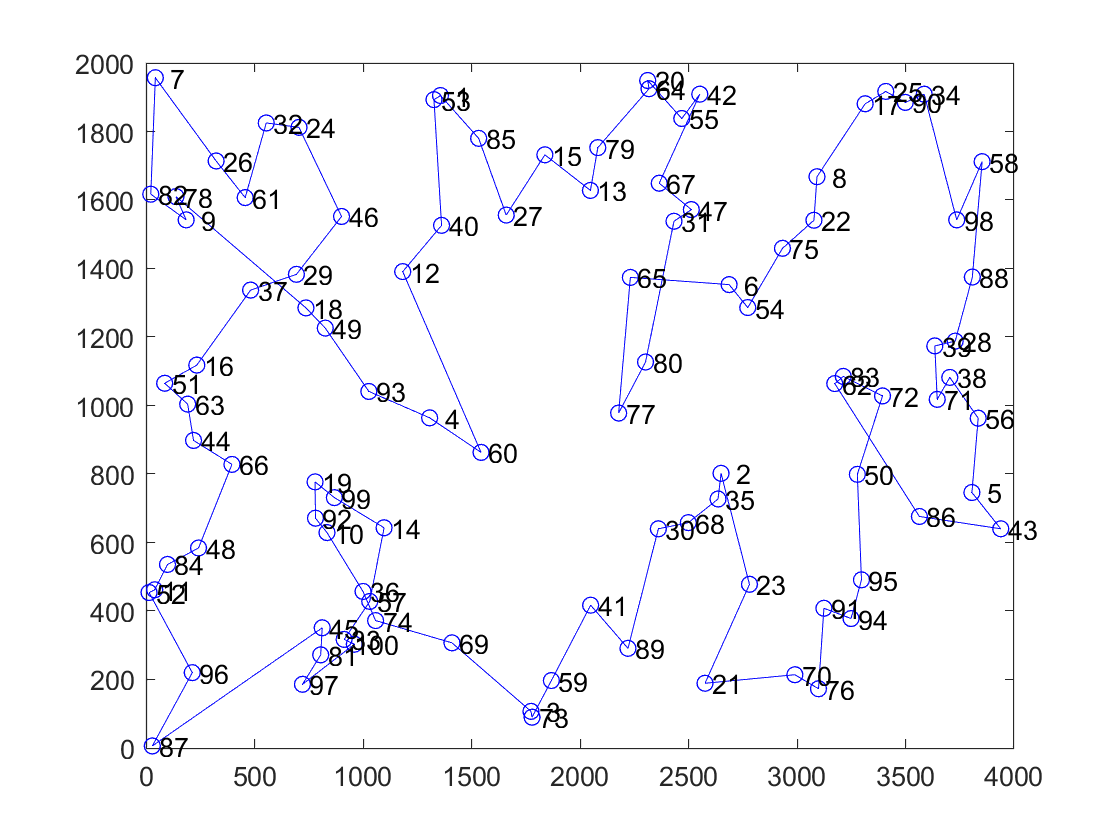

plot_tour(cities, tour)